# load in experiment stats and info tables

clear all;

tabfile = 'C:\Users\bnste\Downloads\JG1150\JG1150_new_bg_stim_tabs.mat';
load(tabfile);

% movie size
height = 512;
width = 512;

% load cell type indicator list here
% -1 is background, 0 is non-red, 1 is red
celltype = zeros(size(maskinds));
celltype(1:52) = 1;
celltype(63) = 1;

% bg mask index
bg_mask_ind = 116;
non_bg_inds = setdiff(1:numel(maskinds),bg_mask_ind);
celltype(bg_mask_ind) = -1;

% responders
isresponder = (1:numel(celltype))==0;
isresponder(1:19) = true;

% get one-cell-stim recids
onestim_recids = filetab.recid(filetab.onecellstim==1);
red_cells = find(celltype == 1);

## calculate some useful quantities for later

% get stimmed cells
stimcells = table(unique(pattab.cell), 'VariableNames',{'cell'});


% get table of stimmed patterns with the cells in those patterns for each
% recid
patcellmatch =removevars(pattab, {'matchpix'});

% make sure we only have given patterns (some may have been removed due to
% bad matching
trialtab = outerjoin(trialtab,pattab,'RightVariables',{'pattern'});
trialtab = trialtab(trialtab.pattern_pattab > 0,{'pattern_trialtab','recid','trial','frame'});
trialtab.Properties.VariableNames{'pattern_trialtab'} = 'pattern';

stattab = outerjoin(stattab, trialtab,'Type','Left','LeftKeys',{'trial','recid'}, 'RightKeys',{'trial','recid'},'RightVariables',{'pattern'});
stattab = stattab(stattab.pattern > 0,:);


% % add cellpattern column to stats table (pattern corresponding to cell)
% stattab = outerjoin( stattab ,patcellmatch, 'RightVariables',{'pattern'});
% stattab.Properties.VariableNames{'pattern'} = 'cellpattern';


% add cellstim boolean (whether this cell is stimmed)
stattab = outerjoin(stattab, patcellmatch, 'Type','left', 'RightVariables',{'cell','pattern'}); %  = cell if pattern includes cell for that trial, otherwise 0
stattab.cellstim = (stattab.cell_stattab == stattab.cell_patcellmatch);
stattab = removevars(stattab,{'cell_patcellmatch', 'pattern_patcellmatch'});
stattab.Properties.VariableNames{'cell_stattab'} = 'cell';
stattab.Properties.VariableNames{ 'pattern_stattab'} =  'pattern';
% add celltype column
stattab.celltype = celltype(stattab.cell);

stattab.onestim = ismember(stattab.recid, onestim_recids);

## calculate stats for stim cells

cellstim_groups = findgroups(stattab.cell, stattab.cellstim);
cellstim_resp_groups = findgroups(stattab.cell, stattab.cellstim, stattab.resptype);

cellstats = grpstats(stattab, {'cell','recid'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});
cellstats_onestim = grpstats(stattab, {'cell', 'onestim'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});
stimstats = grpstats(stattab, {'cell', 'cellstim'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});
stimstats_resptype = grpstats(stattab, {'cell', 'cellstim', 'resptype'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});
stimstats_celltype = grpstats(stattab, { 'cellstim', 'celltype'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});
stimstats_celltype_resptype = grpstats(stattab, { 'cellstim', 'celltype', 'resptype'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});

stimstats_onestim = grpstats(stattab, {'cell', 'cellstim','onestim'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});
stimstats_onestim_resptype = grpstats(stattab, {'cell', 'cellstim', 'resptype','onestim'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});

% get correlation within groups
cellstats.dffstimcorr = splitapply(@(x,y) corr(x,y), double(stattab.respsnr), double(stattab.cellstim), findgroups(stattab.cell, stattab.recid));
cellstats_onestim.dffstimcorr = splitapply(@(x,y) corr(x,y), double(stattab.respsnr), double(stattab.cellstim), findgroups(stattab.cell, stattab.onestim));


## Get background-subtracted traces

Fcent_list_bgsub = containers.Map('KeyType',class(filetab.recid(1)), 'ValueType','any');
Fbg_list = containers.Map('KeyType',class(filetab.recid(1)), 'ValueType','any');
for recind=1:numel(filetab.recid)
    recid = filetab.recid(recind);
    Fc = Fcent_list(recid); % frames x trials x cell
    fcsize = size(Fc);
    Fbg = reshape(Fc(1:fullWindowPreSize-Omitpre,:,bg_mask_ind),[],1);  % want to fit BEFORE stim, when traces aren't as correlated
    Fnobg = reshape(Fc(1:fullWindowPreSize-Omitpre,:,non_bg_inds),[],numel(non_bg_inds));
    Fbgstd = std(Fbg); Fnobgstd = std(Fnobg,0,1);
    Fbgmean = mean(Fbg); Fnobgmean = mean(Fnobg,1);
    Fbg = (Fbg - Fbgmean) ./ Fbgstd; Fnobg = Fnobg ./ Fnobgstd;
    Fbg = [ones(size(Fbg)),Fbg];
    
    % least squares
    beta = zeros(2,numel(non_bg_inds));
    for j=1:size(beta,2)
        beta(:,j) = Fbg \ Fnobg(:,j);
    end

    % nonneg least squares
    betann = zeros(2,numel(non_bg_inds));
    for j=1:size(betann,2)
        betann(:,j) = lsqnonneg(Fbg,Fnobg(:,j ));
    end
    
    
    
    % convex optimization
    %betaopt = fmincon(@(beta) overshootPenaltyFunc(beta,Fbg,Fnobg),betann,[],[],[],[],0,Inf);
    
    % apply linear model to whole traces
    Fbg = reshape(Fc(:,:,bg_mask_ind),[],1);
    Fbg_list(recid) = Fbg;
    Fbg = (Fbg - Fbgmean) ./ Fbgstd;
    Fnobg = reshape(Fc(:,:,non_bg_inds),[],numel(non_bg_inds));
    Fnobg = Fnobg ./ Fnobgstd;
    Fbg = [ones(size(Fbg)),Fbg];
    Fpred = Fbg(:,2)*betann(2,:); % solely the multiplicative factor
    

    Fresid = ones(size(Fnobg) + [0,1]);
    Fresid(:,non_bg_inds) = Fnobg - Fpred;
    Fresid(:,non_bg_inds) = Fresid(:,non_bg_inds) .* Fnobgstd;
    Fresid(:,bg_mask_ind) = Fbgmean + (Fbg(:,2) .* Fbgstd);
    
    Fcent_list_bgsub(recid) = reshape(Fresid, fcsize);
end

## calculate mean response curves for each cell

% set original movie or residuals here
%movmap = Fcent_list_bgsub; % for background -subtracted
movmap = Fcent_list_bgsub; % for raw traces

 
Calling SDPT3 4.0: 56892 variables, 18966 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 18966
 dim. of sdp    var  = 25284,   num. of sdp  blk  = 12642
 dim. of socp   var  = 6322,   num. of socp blk  =  1
 dim. of linear var  = 12644
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|8.6e+03|8.4e+00|3.2e+08| 6.683419e+05  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.206|0.246|6.8e+03|6.4e+00|2.6e+08| 6.295968e+05 -2.261387e+05| 0:0:00| spchol  1  1 
 2|0.807|0.583|1.3e+03|2.7e+00|5.9e+07| 6.388114e


nstimcells = numel(stimcells.cell);
ncells = numel(celltype);
% all the following are indexed by [index of cell in stimcells.cell, index of cell being measured ]
mean_resp = cell(nstimcells,ncells);
std_resp = cell(nstimcells,ncells);
mean_resp_smooth = cell(nstimcells,ncells);
std_resp_smooth = cell(nstimcells,ncells);

prestimindsfull = 1:(fullWindowPreSize - Omitpre);
poststimindsfull = poststiminds(1):size(movmap(1),1);


for istimcell=1:nstimcells
    stimcellnum = stimcells.cell(istimcell);
    tmpstat = stattab(:,{'trial','recid','cell','cellstim'});
    for recind=1:numel(filetab.recid)
        recid = filetab.recid(recind);
        Fc = movmap(recid);
        tmptrialtab = trialtab(trialtab.recid == recid,:);
        %inittrial = min(tmptrialtab.trial);
        inittrial = 1;
        stimtrialnums = tmpstat.trial(tmpstat.recid == recid &  tmpstat.cellstim & tmpstat.cell==stimcellnum);
        nostimtrialnums = tmpstat.trial(tmpstat.recid == recid  & ~tmpstat.cellstim & tmpstat.cell==stimcellnum);
        
        tmptrace = Fc(:,stimtrialnums - inittrial + 1, :); % first open index is frame in window, last open index is cell number
        tmptrace = ( tmptrace([prestimindsfull,poststimindsfull],:,:) - mean(tmptrace(prestimindsfull,:,:),1) ) ./ mean(tmptrace(prestimindsfull,:,:),1) ;   
        if recind==1
            traces = tmptrace;
        else
            traces = cat(2,traces, tmptrace);
        end
    end
    for meascellnum=1:ncells
        mean_resp{istimcell,meascellnum} = mean(traces(:,:,meascellnum),2);
        std_resp{istimcell,meascellnum} = std(traces(:,:,meascellnum),0,2);
        smooth_traces = smoothdata(traces(:,:,meascellnum),1,'gaussian',5);
        mean_resp_smooth{istimcell,meascellnum} = mean(smooth_traces,2);
        std_resp_smooth{istimcell,meascellnum} = std(smooth_traces,0,2);
    end
end

% %% plots
% 
% % plot stim cell responses
% selfstiminds = sub2ind(size(mean_resp),1:nstimcells,stimcells.cell');
% 
% 
% tmp = cat(2,mean_resp{selfstiminds});
% figure; hold on; 
% myaxes = [-inf inf -.05 .1];
% plot( tmp); axis(myaxes); h=plot([numel(prestimindsfull) numel(prestimindsfull)], myaxes([3 4]),'LineStyle','-','Color','r', 'LineWidth',2);
% hold off;
% 
% 
% 
% tmp = cat(2,mean_resp{stimcells.cell});
% figure; hold on; 
% myaxes = [-inf inf -.1 .15];
% plot( tmp); axis(myaxes); h=plot([numel(prestimindsfull) numel(prestimindsfull)], myaxes([3 4]),'LineStyle','-','Color','r','LineWidth',2); 
% hold off;

## cross correlation matrix between stimulated cell indicator and observed cell dff

[grp, id] = findgroups(stattab.cell);
corrmat = zeros(nstimcells,ncells);

for istimcell=1:numel(stimcells.cell)
    stimcellnum = stimcells.cell(istimcell);
    stimtrials = unique(stattab.trial(stattab.cell == stimcellnum & stattab.cellstim));
    corrmat(istimcell,id) = splitapply(@corr ,stattab.dff, ismember(stattab.trial,stimtrials) , grp); 
end

## distance mapping

get mean x,y position for each mask

xavg = zeros(1,numel(maskinds));
yavg = zeros(1,numel(maskinds));
for i=1:numel(maskinds)
    [yinds, xinds] = ind2sub([height width], maskinds{i});
    xavg(i) = mean(xinds(:));
    yavg(i) = mean(yinds(:));
end


xdistmat = xavg - xavg';
ydistmat = yavg -yavg';
distmat = sqrt(xdistmat.^2 + ydistmat.^2);
[icell, istimcell] = ind2sub([numel(maskinds) numel(maskinds)],1:numel(maskinds)^2);
disttab = table(icell', istimcell', distmat(1:numel(maskinds)^2)',xdistmat(1:numel(maskinds)^2)', ydistmat(1:numel(maskinds)^2)' ,'VariableNames',{'viewcell','stimcell','stimdist','stimxdist','stimydist'});
disttab = disttab(ismember(disttab.stimcell,stimcells.cell),:);

## get column for distance from stim (1 cell stim only)

distpattab = outerjoin(pattab, disttab,'LeftKeys',{'cell'},'RightKeys',{'stimcell'}, 'Type','Left' );

trialstimcells = outerjoin(trialtab,pattab,'Keys',{'pattern','recid'}, 'Type','Left');
trialstimcells = trialstimcells(:,{'trial','cell','recid_trialtab'});
% tmp = join(stattab,trialstimcells,'LeftKeys',{'trial','recid'},'RightKeys',{'trial','recid_trialtab'});
% tmp.Properties.VariableNames{'cell_stattab'} = 'cell';
% tmp.Properties.VariableNames{ 'cell_trialstimcells'} =  'stimcell';
% tmp = tmp(tmp.stimcell>0,:);
% tmp = join(tmp,disttab,'LeftKeys',{'cell','stimcell'},'RightKeys',{'viewcell','stimcell'});
% diststats = grpstats(tmp, {'cell','recid'}, {'mean','std' }, 'DataVars', {'dff', 'tscore', 'respsnr'});

tmp2 = outerjoin(disttab,pattab, 'LeftKeys',{'stimcell'},'RightKeys',{'cell'},'RightVariables',{'pattern','recid'});
min_by_pattern = grpstats(tmp2, {'viewcell','pattern','recid'},{'min'},'DataVars','stimdist');
mindisttab = join(tmp2,min_by_pattern,'LeftKeys',{'viewcell','recid','pattern','stimdist'},'RightKeys',{'viewcell','recid','pattern','min_stimdist'});
stattab = join(stattab,mindisttab,'LeftKeys',{'cell','recid','pattern'},'RightKeys',{'viewcell','recid','pattern'},'RightVariables',{'stimdist','stimxdist','stimydist','stimcell'});
clear tmp tmp2;

## distance plots

% dff

 myaxes = [-inf inf -.03 .1];
 
 figure;
 gaps = [.08 .01];
 marg_w = .1;
 marg_h = .08;
 
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('DF/F_0');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.spontdff(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.spontdff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);

% activation / inhibition probability vs distance, based on dff

 

 gaps = [.08 .01];
 marg_w = .1;
 marg_h = .09;

activate_thresh = .1; % dff threshold for activation
inhibit_thresh = -.1;

myaxes = [-inf inf 0 .3];

% activations
figure;
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);

dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('activation probability');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.spontdff(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.spontdff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% inhibition
figure;
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);

dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('inhibition probability');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.spontdff(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1)  < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0)  < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.spontdff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);



% difference

figure;
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);
myaxes = [-inf inf -.2 .2];
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = (stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) > activate_thresh) - (stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('activation prob - inhibit prob');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = (stattab.spontdff(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1) > activate_thresh)-(stattab.spontdff(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1)  < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = (stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0)  > activate_thresh) - (stattab.dff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0)  < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = (stattab.spontdff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) > activate_thresh) - (stattab.spontdff(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);

% activation / inhibition probability vs distance, based on snr

 

 gaps = [.08 .01];
 marg_w = .1;
 marg_h = .09;

activate_thresh = 1; % dff threshold for activation
inhibit_thresh = -1;

myaxes = [-inf inf 0 .3];

% activations
figure;
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);

dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('activation probability');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) > activate_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% inhibition
figure;
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);

dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('inhibition probability');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1)  < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0)  < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) < inhibit_thresh;
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);



% difference

figure;
% histogram for red cells during responder stim
ax = subtightplot(2,2,1,gaps,marg_h, marg_w);
myaxes = [-inf inf -.2 .2];
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = (stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) > activate_thresh) - (stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1) < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
ylabel('activation prob - inhibit prob');
title('red label stim response');
axis(myaxes);

% histogram for red cell spontaneous responses
ax = subtightplot(2,2,2,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1);
dffs = (stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1) > activate_thresh)-(stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder))& stattab.celltype==1)  < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('red label spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);


% histogram for non-red cells
ax = subtightplot(2,2,3,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = (stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0)  > activate_thresh) - (stattab.respsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0)  < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red stim response');
axis(myaxes);
xlabel('Distance from stim site (pixels)');

% histogram for non-red cells (spontaneous)
ax = subtightplot(2,2,4,gaps,marg_h, marg_w);
dists = stattab.stimdist(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0);
dffs = (stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) > activate_thresh) - (stattab.spontrespsnr(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0) < inhibit_thresh);
[binnums, edges] = discretize(dists,0:20:400);
[binmeans,binstds, bincounts] = grpstats(dffs,binnums,{'mean','std','numel'});
pltedges = edges(1:end-1);
bar(pltedges, binmeans);
hold on;
er = errorbar(pltedges, binmeans,2*binstds ./ sqrt(bincounts), 2*binstds ./ sqrt(bincounts));
er.LineStyle = 'none';
hold off;
title('non-red spontaneous response');
ax.YAxisLocation = 'Right';
axis(myaxes);

## get spatial activation map

blursigma = 10; % blurring filter
mapsize = 2*[height width];
mapcenter = round(mapsize/2);
finalzoom = 2;

% red cells



spatial_tab = grpstats(stattab(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==1,:),{'cell','stimcell','resptype'},{'mean'},'DataVars',{'dff','stimxdist','stimydist'});
spatial_spots = sub2ind(mapsize, mapcenter(1)-round(spatial_tab.mean_stimydist), mapcenter(2)-round(spatial_tab.mean_stimxdist));


spatial_map_excite = zeros(mapsize);
spatial_map_inhibit = zeros(mapsize);
spatial_map_dff = zeros(mapsize);

for i=1:numel(spatial_spots)
   if spatial_tab.resptype(i)==1
        spatial_map_excite(spatial_spots(i)) =  spatial_map_excite(spatial_spots(i)) + spatial_tab.GroupCount(i);
   elseif spatial_tab.resptype(i)==-1
       spatial_map_inhibit(spatial_spots(i)) =  spatial_map_inhibit(spatial_spots(i)) + spatial_tab.GroupCount(i);
   end
   spatial_map_dff(spatial_spots(i)) =  spatial_map_dff(spatial_spots(i)) + spatial_tab.mean_dff(i)*spatial_tab.GroupCount(i);
end
spatial_map_excite = spatial_map_excite / sum(spatial_tab.GroupCount);
spatial_map_inhibit = spatial_map_inhibit / sum(spatial_tab.GroupCount);
spatial_map_dff = spatial_map_dff / sum(spatial_tab.GroupCount);

spatial_map_excite = 2 * pi * (blursigma^2) * imgaussfilt(spatial_map_excite, blursigma,'FilterSize',4*ceil(2*blursigma)+1.);
spatial_map_inhibit = 2 * pi * (blursigma^2) *imgaussfilt(spatial_map_inhibit, blursigma,'FilterSize',4*ceil(2*blursigma)+1.);
spatial_map_difference = spatial_map_excite - spatial_map_inhibit;
spatial_map_dff = 2 * pi * (blursigma^2) *imgaussfilt(spatial_map_dff, blursigma,'FilterSize',4*ceil(2*blursigma)+1.);

figure;
subtightplot(2,4,1);
imagesc(spatial_map_excite(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('red cell spatial excitation map'); colorbar()
subtightplot(2,4,2);
imagesc(spatial_map_inhibit(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('red cell spatial inhibition map'); colorbar()
subtightplot(2,4,3);
imagesc(spatial_map_difference(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('red cell spatial net probability map'); colorbar()
subtightplot(2,4,4);
imagesc(spatial_map_dff(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('red cell spatial dff map'); colorbar()



%non-red


spatial_tab = grpstats(stattab(ismember(stattab.stimcell,find(isresponder)) & stattab.celltype==0,:),{'cell','stimcell','resptype'},{'mean'},'DataVars',{'dff','stimxdist','stimydist'});
spatial_spots = sub2ind(mapsize, mapcenter(1)-round(spatial_tab.mean_stimydist), mapcenter(2)-round(spatial_tab.mean_stimxdist));


spatial_map_excite = zeros(mapsize);
spatial_map_inhibit = zeros(mapsize);
spatial_map_dff = zeros(mapsize);

for i=1:numel(spatial_spots)
   if spatial_tab.resptype(i)==1
        spatial_map_excite(spatial_spots(i)) =  spatial_map_excite(spatial_spots(i)) + spatial_tab.GroupCount(i);
   elseif spatial_tab.resptype(i)==-1
       spatial_map_inhibit(spatial_spots(i)) =  spatial_map_inhibit(spatial_spots(i)) + spatial_tab.GroupCount(i);
   end
   spatial_map_dff(spatial_spots(i)) =  spatial_map_dff(spatial_spots(i)) + spatial_tab.mean_dff(i)*spatial_tab.GroupCount(i);
end
spatial_map_excite = spatial_map_excite / sum(spatial_tab.GroupCount);
spatial_map_inhibit = spatial_map_inhibit / sum(spatial_tab.GroupCount);
spatial_map_dff = spatial_map_dff / sum(spatial_tab.GroupCount);

spatial_map_excite = 2 * pi * (blursigma^2) * imgaussfilt(spatial_map_excite, blursigma,'FilterSize',4*ceil(2*blursigma)+1.);
spatial_map_inhibit = 2 * pi * (blursigma^2) *imgaussfilt(spatial_map_inhibit, blursigma,'FilterSize',4*ceil(2*blursigma)+1.);
spatial_map_difference = spatial_map_excite - spatial_map_inhibit;
spatial_map_dff = 2 * pi * (blursigma^2) *imgaussfilt(spatial_map_dff, blursigma,'FilterSize',4*ceil(2*blursigma)+1.);


subtightplot(2,4,5);
imagesc(spatial_map_excite(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('non-red cell spatial excitation map'); colorbar()
subtightplot(2,4,6);
imagesc(spatial_map_inhibit(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('non-red cell spatial inhibition map'); colorbar()
subtightplot(2,4,7);
imagesc(spatial_map_difference(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('non-red cell spatial net probability map'); colorbar()
subtightplot(2,4,8);
imagesc(spatial_map_dff(mapcenter-round(height/(2*finalzoom)):mapcenter+round(height/(2*finalzoom)), mapcenter-round(width/(2*finalzoom)):mapcenter+round(width/(2*finalzoom)))); title('non-red cell spatial dff map'); colorbar()

## traces for each cell; i controls cell; j controls plot type

nplots = 4;
if mod(j,nplots)==1
    tmp = mean_resp{i,stimcells.cell(i)};
    tmpstd = std_resp{i,stimcells.cell(i)};
    figure; hold on; 
    myaxes = [-inf inf -.1 .3];
    plot(tmp);
    %errorbar( tmp, 2*tmpstd); 
    axis(myaxes); h=plot([numel(prestimindsfull) numel(prestimindsfull)], myaxes([3 4]),'LineStyle','-','Color','r', 'LineWidth',2);
    title(sprintf("Same cell stim for stimulation cell %d",stimcells.cell(i)))
    ylabel("DF / F_0"); xlabel("frames");
    hold off;
elseif mod(j,nplots)==2
    tmp = cat(2,mean_resp{i,setdiff(find(celltype == 1),stimcells.cell(i) ) });
    tmp = mean(tmp,2);
    tmpstd = cat(2,std_resp{i,setdiff(find(celltype == 1),stimcells.cell(i) ) });
    tmpstd = rms(tmpstd,2);
    figure; hold on; 
    myaxes = [-inf inf -.1 .3];
    plot( tmp); axis(myaxes); h=plot([numel(prestimindsfull) numel(prestimindsfull)], myaxes([3 4]),'LineStyle','-','Color','r', 'LineWidth',2);
    title(sprintf("Response for other red cells to stimulation cell %d",stimcells.cell(i)));
    ylabel("DF / F_0"); xlabel("frames");
    hold off;
elseif mod(j,nplots)==3
    tmp = cat(2,mean_resp{i,setdiff(find(celltype == 0),stimcells.cell(i) ) });
    tmp = mean(tmp,2);
    tmpstd = cat(2,std_resp{i,setdiff(find(celltype == 1),stimcells.cell(i) ) });
    tmpstd = rms(tmpstd,2);
    figure; hold on; 
    myaxes = [-inf inf -.1 .3];
    plot( tmp); axis(myaxes); h=plot([numel(prestimindsfull) numel(prestimindsfull)], myaxes([3 4]),'LineStyle','-','Color','r', 'LineWidth',2);
    title(sprintf("Response for non-red cells to stimulation cell %d",stimcells.cell(i)));
    ylabel("DF / F_0"); xlabel("frames");
    hold off;
else
    tmp = mean_resp{i,bg_mask_ind};
    tmpstd = std_resp{i,bg_mask_ind};
    figure; hold on; 
    myaxes = [-inf inf -.1 .3];
    plot(tmp);
    %errorbar( tmp, 2*tmpstd); 
    axis(myaxes); h=plot([numel(prestimindsfull) numel(prestimindsfull)], myaxes([3 4]),'LineStyle','-','Color','r', 'LineWidth',2);
    title(sprintf("Background response for stimulation cell %d",stimcells.cell(i)))
    ylabel("DF / F_0"); xlabel("frames");
    hold off;
end
i=i+(mod(j,nplots)==0);
j=j+1;

## investigate smoothed trial traces

cellind = 1;
recind = 1;

trialind=1;
window = [1:prestimindsfull(end) poststimindsfull(1):size(Fcent_list(1),1)];

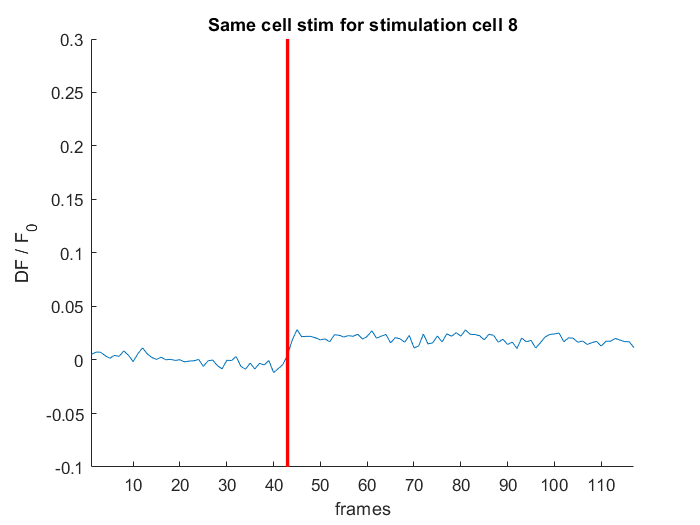

Fc = Fcent_list(recind);

plot(smooth(window, Fc(window,trialind,cellind), 0.3, 'loess')); title(sprintf('movie %d, cell %d, trial %d', recind, cellind, trialind) )
if trialind < size(Fc,2)
    trialind = trialind+1;

else
    trialind = 1;
    cellind = cellind + 1;
end

## get spatial activation map from multistim experiments (old)

blursigma = 5; % blurring filter

% get relevant vids
msrecs = filetab.recid(filetab.ncellstim == 18 & ~filetab.onecellstim);
multistim_cells = sort(unique(pattab.cell(ismember(pattab.recid,msrecs))));

% get excitation and inhibition probabilities by recid, cell
total_tab = groupsummary(stattab(ismember(stattab.recid, msrecs),{'cell','recid','respsnr'}), {'cell','recid'});
total_counts = total_tab.GroupCount;
excite_tab = groupsummary(stattab(ismember(stattab.recid, msrecs) & stattab.resptype==1,{'cell','recid','respsnr'}), {'cell','recid'}, 'IncludeEmptyGroups',true);
inhibit_tab = groupsummary(stattab(ismember(stattab.recid, msrecs) & stattab.resptype==-1,{'cell','recid','respsnr'}), {'cell','recid'}, 'IncludeEmptyGroups',true);
total_tab.exciteprob = excite_tab.GroupCount ./ total_tab.GroupCount;
total_tab.inhibitprob = inhibit_tab.GroupCount ./ total_tab.GroupCount;


% get mean x,y position for each mask
xavg = zeros(1,numel(maskinds));
yavg = zeros(1,numel(maskinds));
for i=1:numel(maskinds)
    [yinds, xinds] = ind2sub([height width], maskinds{i});
    xavg(i) = mean(xinds(:));
    yavg(i) = mean(yinds(:));
end

% for each mask find the closest stimmed mask and the displacement from
% the stimmed mask to the given mask
closeststim = zeros(1,numel(maskinds));
closestdispx = zeros(1,numel(maskinds));
closestdispy = zeros(1,numel(maskinds));
for i=1:numel(maskinds)
    [~, closeststim(i)] = min( (xavg(multistim_cells) - xavg(i)).^2 + (yavg(multistim_cells) - yavg(i)).^2 );
    closestdispx(i) = round(xavg(i) - xavg(multistim_cells(closeststim(i))));
    closestdispy(i) = round(yavg(i) - yavg(multistim_cells(closeststim(i))));
end




% use displacements to create a weighted mean plot centered on stim sites
newheight = 2*height; newwidth=2*width;
excite_result = zeros(newheight, newwidth);
inhibit_result = zeros(newheight, newwidth);
% go through videos and get stim-centered averages
centery = round(newheight / 2);
centerx = round(newheight / 2);


% create spatial cell weighting image (blurred)
cell_weights = zeros(newheight, newwidth) + 1e-8;
for i=1:numel(maskinds)
    [celly,cellx] =  ind2sub([height width], maskinds{i});
    newx = round(cellx - xavg(i) + centerx + closestdispx(i)); newy = round(celly - yavg(i) + centery +  closestdispy(i));
    newinds = sub2ind([newheight newwidth],newy,newx);
    cell_weights(newinds) = cell_weights(newinds) + 1;
end
cell_weights = imgaussfilt(cell_weights,blursigma);


for irec=1:numel(msrecs)
    recexresult = zeros(newheight, newwidth);
    recinresult = zeros(newheight, newwidth);
    for icell=1:numel(maskinds)
        exweight = total_tab.exciteprob(total_tab.cell == icell & total_tab.recid == msrecs(irec));
        inweight = total_tab.inhibitprob(total_tab.cell == icell & total_tab.recid == msrecs(irec));
        [celly,cellx] =  ind2sub([height width], maskinds{icell});
        newx = round(cellx - xavg(icell) + centerx + closestdispx(icell)); newy = round(celly - yavg(icell) + centery +  closestdispy(icell));
        newinds = sub2ind([newheight newwidth],newy,newx);
        recexresult(newinds) = recexresult(newinds) +  exweight  ;
        recinresult(newinds) = recinresult(newinds) +  inweight   ;
    end
    
    excite_result = excite_result + ( recexresult / numel(msrecs));
    inhibit_result = inhibit_result + ( recinresult / numel(msrecs));
    
end

excite_result = imgaussfilt(excite_result, blursigma) ./ cell_weights;
inhibit_result = imgaussfilt(inhibit_result, blursigma) ./ cell_weights;

diff_result = excite_result - inhibit_result;

climex = .8;
climin = .3;
figure; imagesc(excite_result( (1:height) + centery - round(height/2),(1:width) + centerx - round(width/2))); colorbar; caxis([0 climex]); axis equal;
figure; imagesc(inhibit_result( (1:height) + centery - round(height/2),(1:width) + centerx - round(width/2))); colorbar; caxis([0 climin]); axis equal;
figure; imagesc(diff_result( (1:height) + centery - round(height/2),(1:width) + centerx - round(width/2))); colorbar; caxis([-climin climex]); axis equal

## Function Definitions

function penalty =  overshootPenaltyFunc(beta, Fbg, Fnobg)
    resid = reshape(Fnobg - Fbg*beta,1,[]);
    penalty = sum(resid.^2) + sum(exp(resid));
end